# Base example

## Introduction

In this base example, we will present some of the key concepts related to MONSTeR, what it is required to setup a simulation and what results one might expect to browse.

## Simulation setup

In the simulation setup, an instance of the class **MonsterConfig** is required. This object provides all the configuration details for the simulation and its many options are organised in logical groups, for example *Traffic*, *Layout*, *Users*, etc.

close all;

% Get configuration
Config = MonsterConfig();


Once the **Config** instance is available, it is possible to modify its details to fit the scenario under investigation.

In this case we will setup a simulation in a Manhattan grid with 3 macro eNodeB sites, each with 3 cells, no micro eNodeB sites and 10 users for 10 simulation rounds of 1 ms each.

Config.Runtime.simulationRounds = 10;
Config.Runtime.seed = 126;
Config.SimulationPlot.runtimePlot = 1;
Config.Logs.logLevel = 'ERR';
Config.MacroEnb.sitesNumber = 1;
Config.MacroEnb.cellsPerSite = 3;
Config.MicroEnb.sitesNumber = 0;
Config.Ue.number = 10;
Config.Mobility.scenario = 'pedestrian';
Config.Terrain.type = 'manhattan';
Config.Channel.shadowingActive = true;
Config.Channel.losMethod = '3GPP38901-probability';
Config.Traffic.primary = 'fullBuffer';
Config.Traffic.arrivalDistribution = 'Static';
Config.Traffic.static = 0;


Once the customisation of the simulation scenario are completed, we need to create an instance of the **MonsterLog** class, that is used to manage logging throughout this simulation.


Logger = MonsterLog(Config);
Logger.log('(EXAMPLES - BASE) configured simulations and started initialisation', 'NFO');


Finally, the configuration and the logger instances can be passed to the **Monster** constructor that will generate a simulation object with the specified setup.

Simulation = Monster(Config, Logger);
Simulation.Logger.log('(EXAMPLES - BASE) main simulation instance created', 'NFO');


## Simulation runtime

The *Simulation *object created above is used to control the execution of the overall simulation.

MONSTeR is designed around the concept of discrete time evolution based on the eNodeB's scheduling period of 1 ms. This means that the parameter *Config.Runtime.simulationRounds *sets the duration of a simulation.

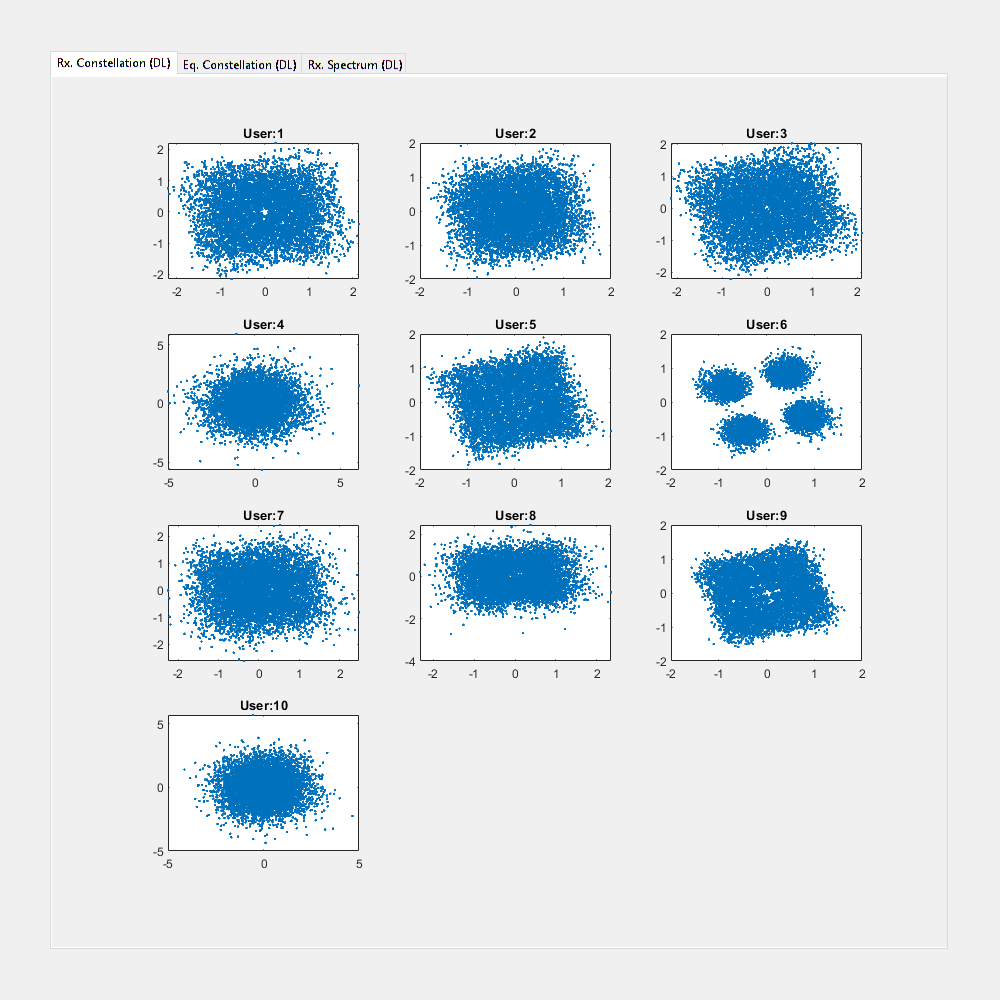

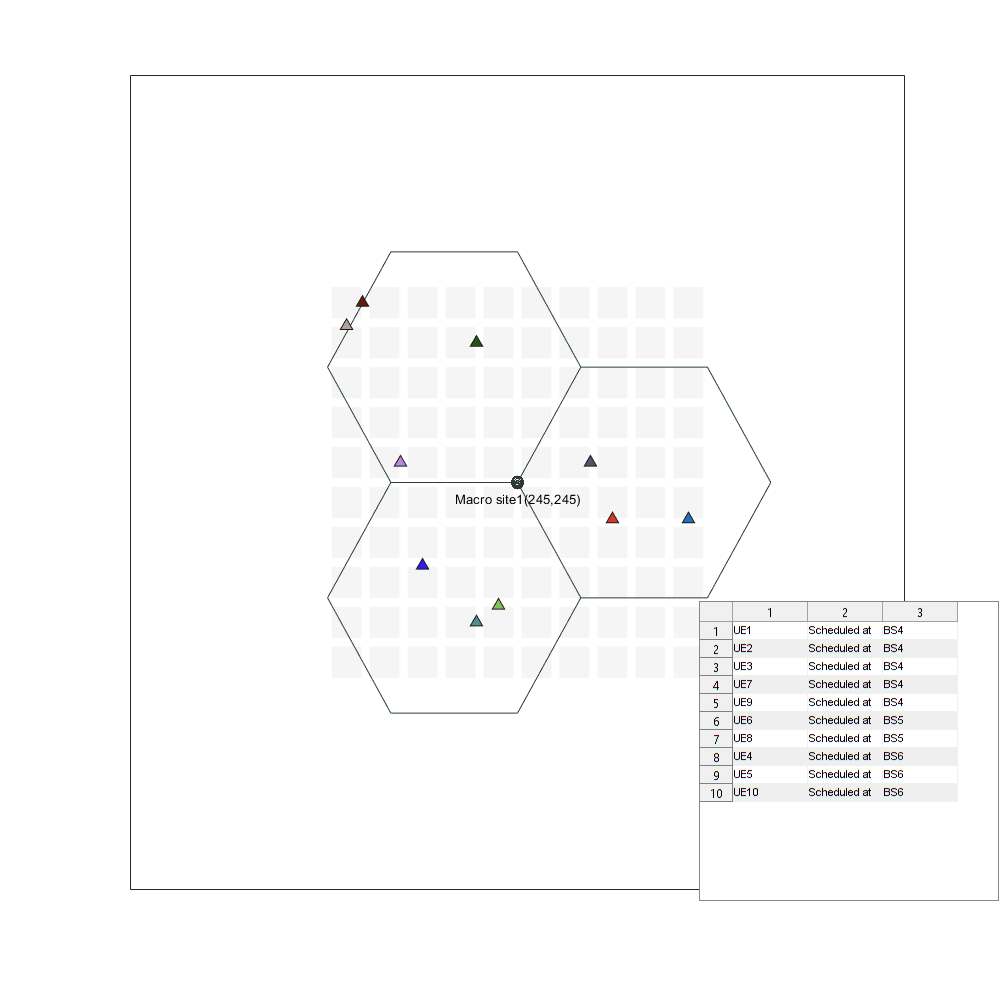

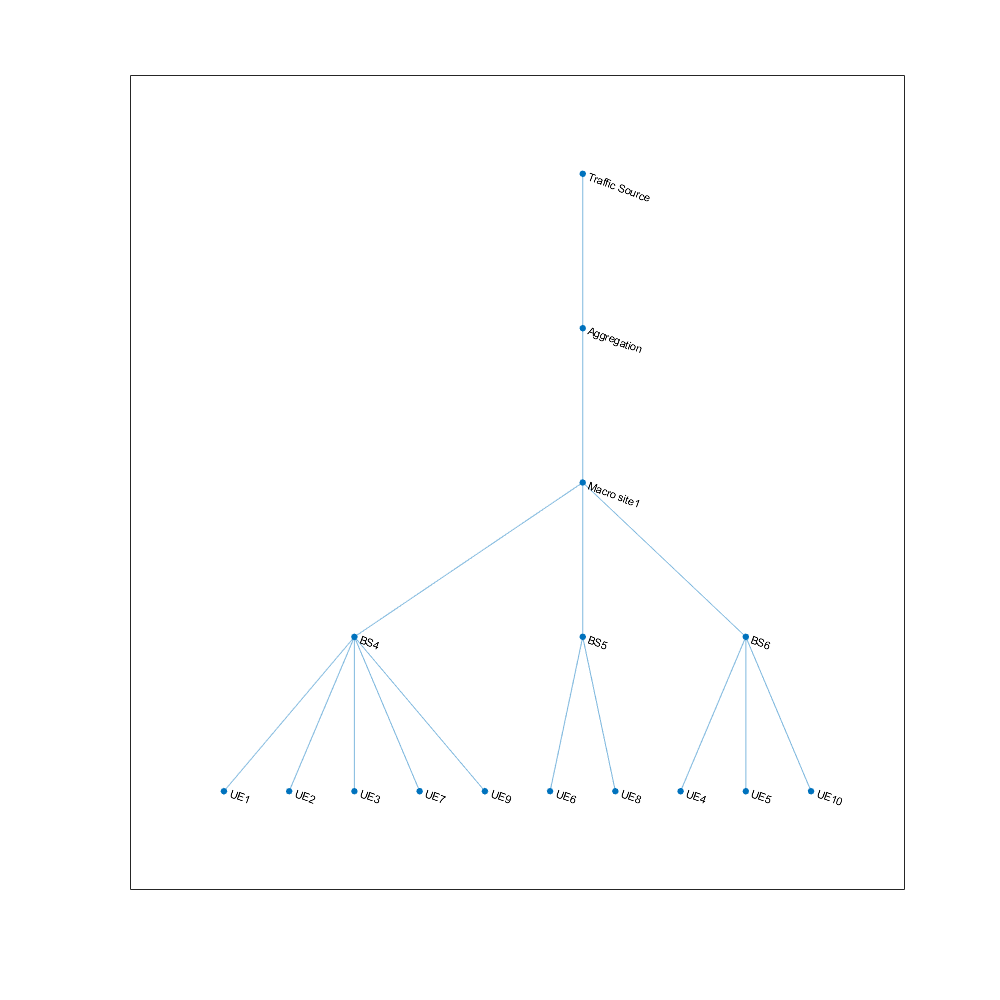


for iRound = 0:(Simulation.Runtime.totalRounds - 1)
    Simulation.setupRound(iRound);	
    Simulation.run();
    Simulation.collectResults();
    Simulation.clean();
end